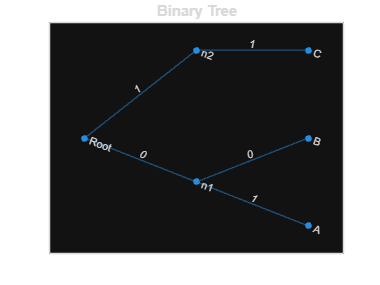

% Define the tree nodes and edges
nodes = {'Root', 'n1', 'n2','A','B','C'};
edges = { {'Root', 'n1'}, {'Root', 'n2'}, {'n1', 'A'}, {'n1', 'B'}, {'n2', 'C'}}; % Corrigido

% Create a graph
G = graph();
for i = 1:numel(nodes)
    G = addnode(G, nodes{i});
end

% Add edges to the graph
for i = 1:size(edges, 2)
    G = addedge(G, edges{i}{1}, edges{i}{2});
end

% Plot the graph
h = plot(G);



% Label edges with weights
weights = {'0', '1', '1', '0', '1'}; 
labeledge(h, [1, 1, 2, 2, 3], [2, 3, 4, 5, 6], weights);

% Adjust the layout
layout(h, 'layered', 'Direction', 'right', 'Sources', 'Root');
title('Binary Tree');
saveas(h,'./aula08/Binary_Tree.png');